# 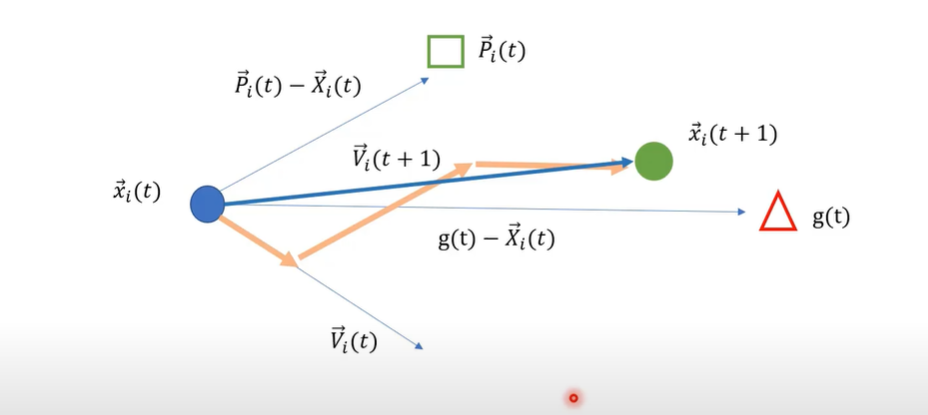

# Diccionario PSO


$$\begin{array}{l}
x_i \left(t\right):\textrm{Posicion}\;\textrm{en}\;x,y\\
v_i \left(t\right)\;;\textrm{Velocidad}\;\textrm{de}\;\textrm{cada}\;\textrm{particula}\\
\textrm{gBest}=\textrm{mejor}\;\textrm{posicion}\;\textrm{global}\\
\textrm{pBest}=\textrm{mejor}\;\textrm{posicion}\;\textrm{de}\;\textrm{la}\;\textrm{particula}
\end{array}$$


# Principios (Modelos de Vida Artificial)

- Proximidad

- Calidad

- Respuesta diversa 

- Estabilidad

- Adaptabilidad

# Funcion de Vuelo


$$\begin{array}{l}
v_i \left(t+1\right)=W\;v_i \left(t\right)+c_1 \textrm{Rand}\left(\textrm{pBest}-x_i \left(t\right)\right)+c_2 \textrm{Rand}\left(\textrm{gBest}\left(t\right)-x_i \left(t\right)\right)\\
w:\textrm{Factor}\;\textrm{de}\;\textrm{Inercia}\\
w\;\textrm{alto}\;\textrm{Diversificasion}\\
w\;\textrm{bajo}\;\textrm{Intensificacion}\\
w=\left\lbrack \frac{w_{\min } -w_{\max } }{{\textrm{iter}}_{\max } -1}*\left(\textrm{iter}-1\right)\right\rbrack +w_{\max } 
\end{array}$$


#### constantes de aceleracion $c_1 \textrm{Rand}\;\&\;C_2 \textrm{Rand}$

- c1,c2 -> constantes de aceleracion

- c1>0 y c2 = 0 prima el comportamiento individual

- c1=0 y c2>0 prima el comportamiento colectivo

- c1=c2>0 valor promedio entre individual y colectivo

- c1 > c2>0 experiencia individual mejor que la de grupo

- 
$$c_1 =\frac{c_{1\min } -c_{1\max } }{{\mathrm{iter}}_{\max } }*\mathrm{iter}+c_{1\max }$$


- 
$$c_2 =\frac{c_{2\;m\mathrm{ax}} -c_{2\;\min } }{{\mathrm{iter}\;}_{\max } }*\mathrm{iter}+c_{2\;\min }$$


# Funcion de Posicion


$$x_{i\;} \left(t+1\right)=x\left(t\right)+v_i \left(t+1\right)$$


# Algoritmo PSO

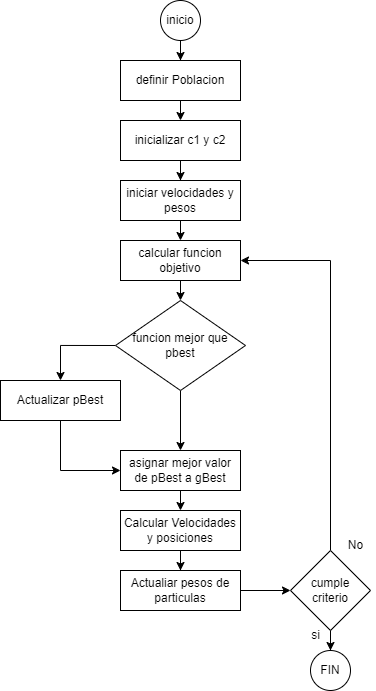

# Coding....

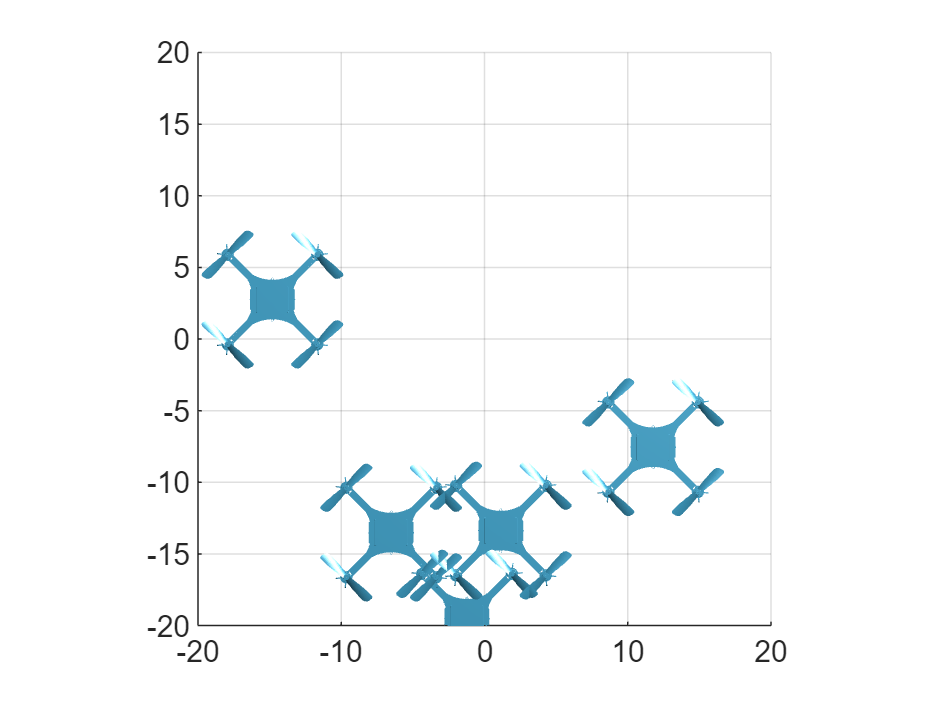

% crear poblacion
objFun = @(x1,x2) x1^2 + x2^2 + sin(x1)*cos(x2);

Np = 5;
Min = [-20 -20];
Max = [20 20];
pop = createParticles(Np,Min,Max);


nd      = ndims(Max);
maxIter = 40;
cmin    = [0.5 0.5];
cmax    = [2.5 2.5];
wmin    = 0.4;
wmax    = 0.9;
alpha   = 1;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

scene=figure;                                                               % new figure
tam = [1 1 800 600];
set(scene,'position',[tam(1) tam(2) tam(3) tam(4)]);                        % position and size figure in the screen

axis equal;                                                                 % Set axis aspect ratios
axis([-20 20 -20 20 -10 10]);                                               % Set axis limits 
grid on;                                                                    % Display axes grid lines
SwarmFcn;                                                                   % Parameters of robot
M1=swarmPlot(pop);                                                          % Plot robot in initial position hx,hy and phi orientation
camlight('rigth');

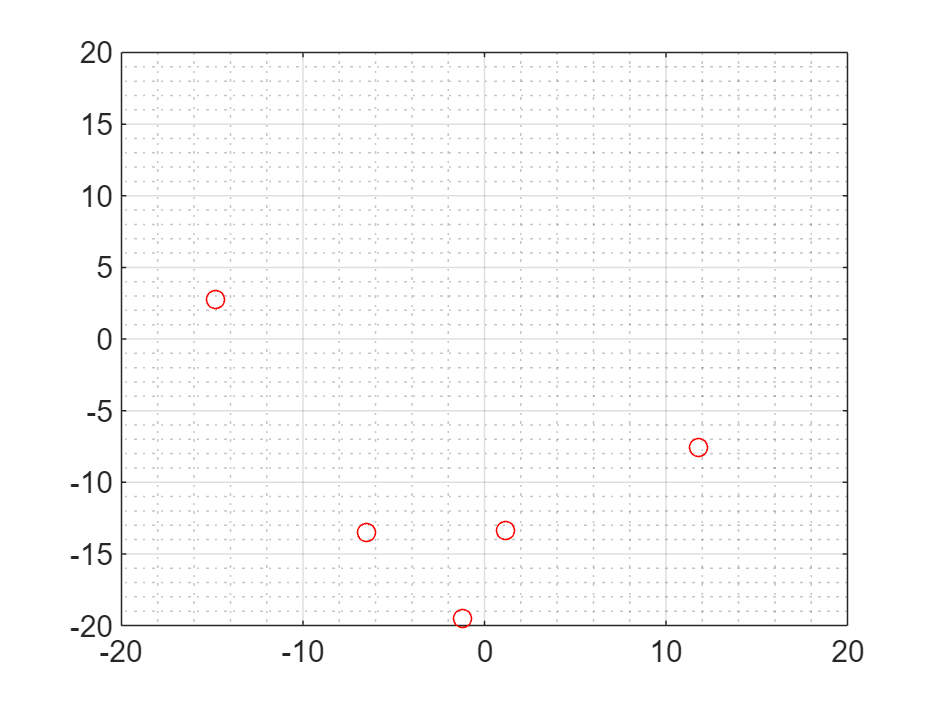

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

FA = fcnAdaptPSO(objFun,pop);

vi = 0; 
Vel = velInitPso(Np,nd,vi);

iter  =1;
pBest = pop;
[velmin,posmin]=min(FA);
gBest = pop(posmin,:);

figure(iter)
plot(pop(:,1), pop(:,2), 'ro')
grid on
grid minor
axis([Min(1) Max(1) Min(2) Max(2)])

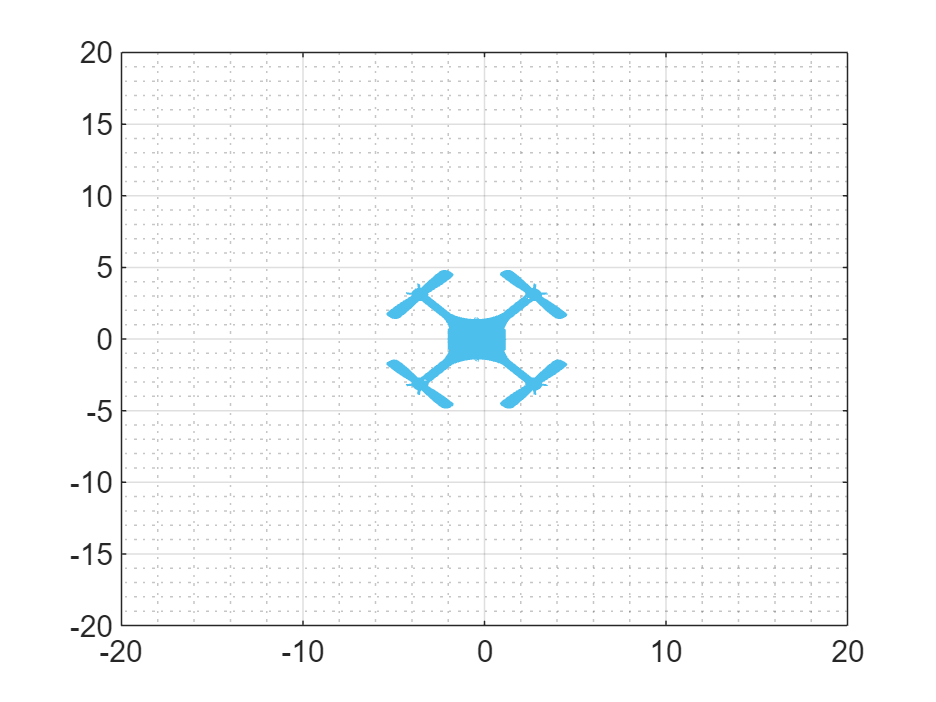


matC1 = zeros(maxIter,1);
matc2 = zeros(maxIter,1);
matw  = zeros(maxIter,1);

V = Vel;
X = pop;

while iter <= maxIter
    W   = calcWPSO(wmin,wmax,iter,maxIter);
    matw(iter,1)  = W;
    c1  = calcC1PSO(cmin(1),cmax(1),iter,maxIter);
    matC1(iter,1) = c1;
    c2  = calcC2PSO(cmin(2),cmax(2),iter,maxIter);
    matc2(iter,1) = c2;
    
    [V] = calcVelPSO(X,W,V,c1,c2,pBest,gBest);
    [X] = calcPosPSO(X,V);
    [F] = fcnAdaptPSO(objFun,X);

    [pBest, FOBest] = pMejores(objFun,pBest,X,F);
    
    [v,p] = min(FOBest) ;
    gBest = pBest(p,:);

    pause(0.1);
    plot(X(:,1),X(:,2),'ro')
    grid on
    grid minor
    axis([Min(1) Max(1) Min(2) Max(2)])

    iter = iter+1;
     
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
     delete (M1)
     M1 = swarmPlot(X);
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


end